**The simulations of imprinting.**

**For Figure S9.**

% Basic paramters
load ../Parameter_determination/Basic_parameters.mat

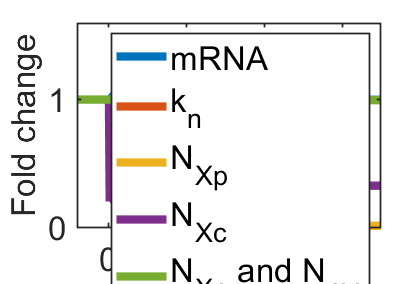

para0=para_opt;

Vn=2.8;
Vc=37.2;
Kv=5.8262;
para1=[para0,Vn,Vc,Kv];


%Numerically solve the initial values of molecules in WT cells
load ../Solve_values/Solve_values.mat
syms_solve=[Xn_pre,Xc_pre,Xp_pre,Yn_pre,Yp_pre];
syms k0 Kx Ky Km am ax ay bm bx Xt Yt Vn Vc Kv
para_sym=[k0 Kx Ky Km am ax ay bm bx Xt Yt Vn Vc Kv];
para_num=para1;
%para:[k0 Kx Ky Km am ax ay bm bx Xt Yt]
temp1=double(subs(syms_solve,para_sym,para_num));% Xn Xc Xp Yn Yp
temp1=temp1(~any(temp1<0,2),:);
temp2=[2.8*para0(7)/para0(5),37.2*para0(9)/para0(8)];% mn mc

y_ini=[temp2,temp1];
y_ini(3)=y_ini(1); %set Xn = mn



% Calculate the homeostatic values
tspan=[1:1:1e4];
[~,y_tot]=ode15s(@(t,y)diffun(y,para1),tspan,y_ini);
y_ini2=y_tot(end,:);



% Simulating the depletion of Xc
y_ini3=y_ini2;
y_ini3(4)=y_ini2(4)*0.2;

tspan=[1:1:2e4];
[~,y_tot2]=ode15s(@(t,y)diffun(y,para1),tspan,y_ini3);

y_all=[y_tot(end-1e3:end,:);y_tot2(1:2e4,:)];



% Setting the paramters and calculate values
mn=y_all(:,1);
mc=y_all(:,2);
Xn=y_all(:,3);
Xc=y_all(:,4);
Xp=y_all(:,5);
Yn=y_all(:,6);
Yp=y_all(:,7);
m_all=mn+mc;


k0=para0(1);
am=para0(5);
ax=para0(6);
ay=para0(7);
bx=para0(9);
bm=para0(8);
Kx=para0(2);
Km=para0(4);
Vn=2.8;
Vc=37.2;
Ky=para0(3);
Xt=para0(10);
Yt=para0(11);
Kv=5.8262;

kn=k0*Vn./(Vn+Kv).*(Xp./(Xp+Kx*Vn)).*Vn.*Km./(Vn*Km+mn).*Yp./(Yp+Ky*Vn);


%%% Plot
colors=["#0072BD"
    "#D95319"
    "#EDB120"
    "#7E2F8E"
    "#77AC30"
    "#4DBEEE"
    "#A2142F"
    '#FF0000'
    '#00FF00'
    '#0000FF'
    '#00FFFF'
    '#FF00FF'
    '#FFFF00'
    '#000000'
    '#FFFFFF'];


% Simulations 
t_all=[1:length(y_all(:,1))]-1e3;

fig=figure;
set(fig,'Position',[300 100 1000 700]);

ax1=axes('position', [0.19 0.2 0.75 0.72]);

p1=plot(t_all,m_all/m_all(1), ...
    "LineWidth",5, ...
    "Color",colors(1),...
    "DisplayName","mRNA");
hold on

p2=plot(t_all,kn/kn(1), ...
    'DisplayName',"k_n", ...
    "Color",colors(2),...
    "LineWidth",5);

hold on

p3=plot(t_all,Xp/Xp(1), ...
    'DisplayName',"N_{Xp}", ...
    "Color",colors(3),...
    "LineWidth",5);
hold on

p4=plot(t_all,Xc/Xc(1), ...
    'DisplayName',"N_{Xc}", ...
    "Color",colors(4),...
    "LineWidth",5);

p5=plot(t_all,Xn/Xn(1), ...
    'DisplayName',"N_{Xn} and N_{mn}", ...
    "Color",colors(5),...
    "LineWidth",5);

hold off
xlim([-40,350])
ylim([0,1.6])

set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
set(gca,'Layer','top')
box(gca,'on')
legend([p1 p2 p3 p4 p5],"Interpreter","tex","FontSize",20)
xlabel('Time (min)','interpreter','tex','FontSize',20);
ylabel('Fold change','interpreter','tex','FontSize',20);


function dydt = diffun(y,para)
%%% Differential equations of the system

%y:[mn mc Xn Xc Xp Yn Yp]
mn=y(1);
mc=y(2);
Xn=y(3);
Xc=y(4);
Xp=y(5);
Yn=y(6);
Yp=y(7);

%para:[k0 Kx Ky Km am ax ay bm bx Xt Yt]
Kv=5.8262;%fL
k0=para(1);
Kx=para(2);
Ky=para(3);
Km=para(4);
am=para(5);
%ax=para(6);
ay=para(7);
bm=para(8);
bx=para(9);
%Xt=para(10);
%Yt=para(11);


dydt = zeros(7,1);
%dydt:[dmndt dmcdt dXndt dXcdt dXpdt dYndt dYpdt]

Vn=2.8;%fL
Vc=37.2;%fL

kn=(k0*Vn/(Vn+Kv))*(Xp/(Xp+Kx*Vn))*Vn*Km/(Vn*Km+mn)*Yp/(Yp+Ky*Vn);

dydt(1)=kn-am*(Yn/Vn)*mn;
dydt(2)=am*(Yn/Vn)*mn-bm*(Xc/Vc)*mc;
dydt(3)=kn-am*(Yn/Vn)*mn;
dydt(4)=am*(Yn/Vn)*mn-bx*Xc;
dydt(5)=bx*Xc-kn;
dydt(6)=kn-ay*Yn;
dydt(7)=ay*Yn-kn;

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


